# **Quickly apply gravity loads and obtain mass and stiffness matrices**

**This demonstrates how to quickly create gravity loads based on the mass matrix.**

**It also demonstrates how to obtain the model's stiffness, mass, and damping matrices.**

clc; clear;

opsMAT = OpenSeesMatlab();
ops = opsMAT.opensees;

### FE Model

ops.wipe()
ops.model("basic", "-ndm", 2, "-ndf", 3)

% Define the model nodes
ops.node(1, 0.0, 0.0)
ops.node(2, 2.0, 0.0)
ops.node(3, 0.0, 2.0)
ops.node(4, 0.0, 2.0)
ops.node(5, 2.0, 2.0)
ops.node(6, 2.0, 2.0)

% Constrain the nodes
ops.rigidLink("beam", 3, 4)  % Rigid link between nodes 3 and 4
ops.equalDOF(5, 6, 1, 2, 3)  % Equal DOF between nodes 5 and 6

ops.fix(1, 1, 1, 1)
ops.fix(2, 1, 1, 1)

% Assign the node masses
ops.mass(1, 1.0, 1.0, 0.0)
ops.mass(2, 1.0, 1.0, 0.0)
ops.mass(3, 1.0, 1.0, 0.0)
ops.mass(4, 1.0, 1.0, 0.0)
ops.mass(5, 10.0, 10.0, 1e-3)
ops.mass(6, 10.0, 10.0, 1e-3)

% Define the elements
ops.geomTransf("Linear", 1)

% element('elasticBeamColumn', eleTag, *eleNodes, Area, E_mod, Iz, transfTag, <'-mass', mass>)
Area = 1.0;
E_mod = 1.0;
Iz = 1.0;
ops.element("elasticBeamColumn", 1, 1, 3, Area, E_mod, Iz, 1, "-mass", 1.0)
ops.element("elasticBeamColumn", 2, 2, 5, Area, E_mod, Iz, 1, "-mass", 1.0)
ops.element("elasticBeamColumn", 3, 4, 6, Area, E_mod, Iz, 1, "-mass", 1.0)

## Apply the gravity load

The opstool utility provides a function ``pre.createGravityLoad`` to quickly apply gravity loads. **This function internally retrieves all masses in the model, including those defined at nodes, in elements, and in materials.** You only need to provide the multiplier (gravitational acceleration) and the direction of load application.

ops.timeSeries("Constant", 1)  % Define a constant time series, tag = 1
ops.pattern("Plain", 1, 1)  % Define a load pattern, tag = 1
node_loads = opsMAT.pre.createGravityLoad(direction="Y", factor=-9.81);  % Create gravity loads in the pattern tag=1
display(node_loads);

node_loads =   Map - 属性:

        Count: 6
      KeyType: double
    ValueType: any


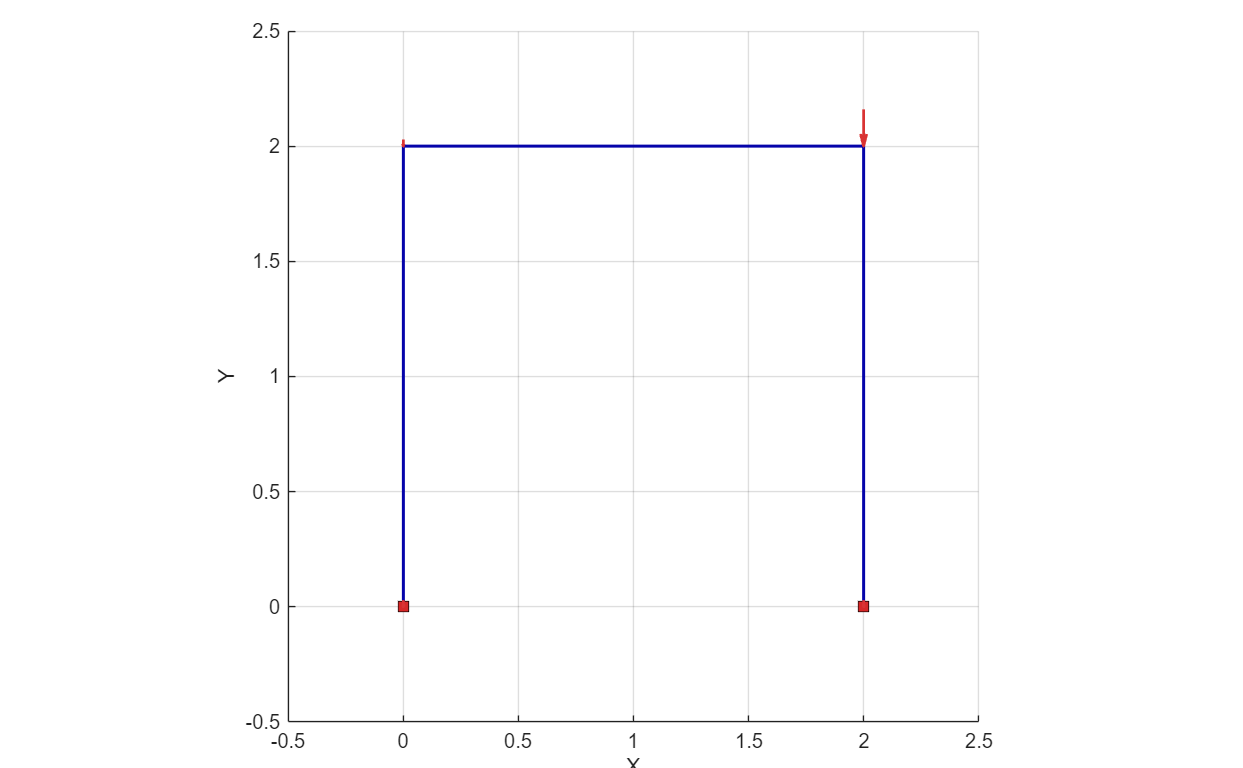

figure;
opts = opsMAT.vis.defaultPlotModelOptions;
opts.loads.showNodal = true;
opsMAT.vis.plotModel(opts=opts);

🤖 Therefore, you can easily create gravity loads directly through the above commands. The way you specify the mass when modeling is arbitrary. opstool can help you do all the internal conversions!

## Get Model Mass

``pre.getNodeMass`` returns a dictionary containing all masses defined in the model, both at nodes and elements.

node_mass = opsMAT.pre.getNodeMass();

ks = keys(node_mass);
vs = values(node_mass);
for i = 1:numel(ks)
    fprintf('Key: ');
    disp(ks{i});

    fprintf('Value: ');
    disp(vs{i});
end

Key: 

     1



Value: 

     2     2     0



Key: 

     2



Value: 

     2     2     0



Key: 

     3



Value: 

     2     2     0



Key: 

     4



Value: 

     2     2     0



Key: 

     5



Value: 

   11.0000   11.0000    0.0010



Key: 

     6



Value: 

   11.0000   11.0000    0.0010



### Get system matrix

#### **Get Matrix from Penalty-constraint method**

constraints_args = {"Penalty", 1e10, 1e10};  % This affects the dimensions of the matrix
system_args = {"FullGeneral"}; % Full matrix system must be used
numberer_args = {"RCM"};  % It affects the topology of the matrix and the order of dof.

M = opsMAT.pre.getMCK("m", constraintsArgs=constraints_args, systemArgs=system_args, numbererArgs=numberer_args);
K = opsMAT.pre.getMCK("k", constraintsArgs=constraints_args, systemArgs=system_args, numbererArgs=numberer_args);
M.Data

ans = 1.0e+10 *

    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    1.0000         0         0   -1.0000         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    1.0000         0         0   -1.0000         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0    1.0000         0        

M.Labels  % nodeTag-dof

ans = 18×1 cell 数组
    {'2-0' }
    {'2-1' }
    {'2-2' }
    {'5-3' }
    {'5-4' }
    {'5-5' }
    {'6-6' }
    {'6-7' }
    {'6-8' }
    {'4-9' }
    {'4-10'}
    {'4-11'}
    {'3-12'}
    {'3-13'}
    {'3-14'}
    {'1-15'}
    {'1-16'}
    {'1-17'}


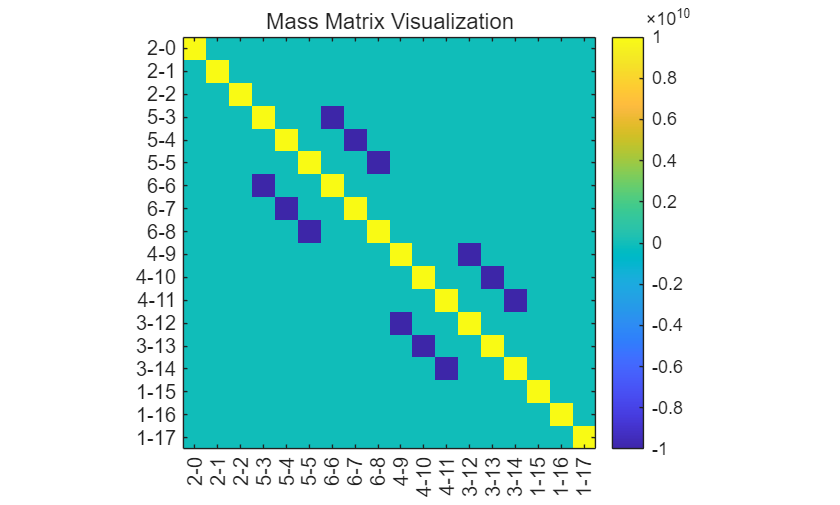

figure;
imagesc(M.Data);
axis equal tight;
colormap(parula);   % turbo, jet ...
colorbar;

xticks(1:numel(M.Labels));
yticks(1:numel(M.Labels));
xticklabels(M.Labels);
xtickangle(90);
yticklabels(M.Labels);

title('Mass Matrix Visualization');

It can be observed that all degrees of freedom are preserved in the system matrix, and a large penalty number is added.

#### **Get Matrix from Transformation-constraint approach**

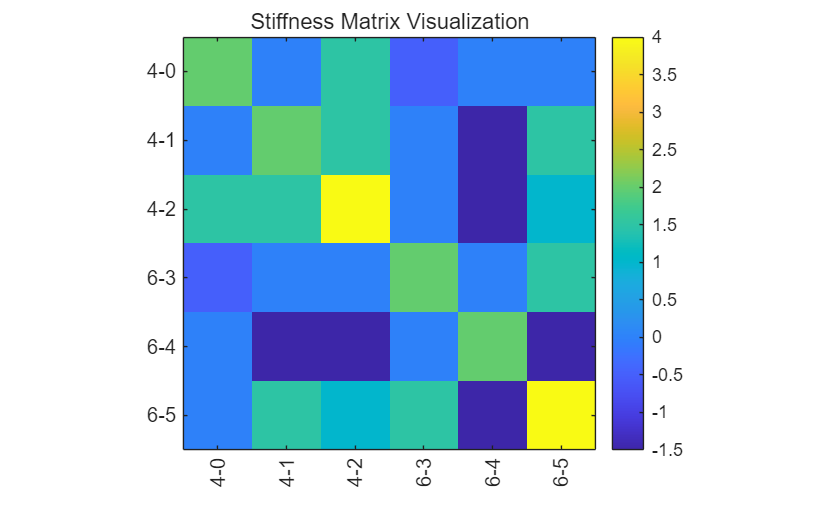

constraints_args = {"Transformation"};  % This affects the dimensions of the matrix
system_args = {"FullGeneral"};  % Full matrix system must be used
numberer_args = {"Plain"};  % It affects the topology of the matrix and the order of dof.

M = opsMAT.pre.getMCK("m", constraintsArgs=constraints_args, systemArgs=system_args, numbererArgs=numberer_args);
K = opsMAT.pre.getMCK("k", constraintsArgs=constraints_args, systemArgs=system_args, numbererArgs=numberer_args);

figure;
imagesc(K.Data);
axis equal tight;
colormap(parula);   % turbo, jet ...
colorbar;

xticks(1:numel(K.Labels));
yticks(1:numel(K.Labels));
xticklabels(K.Labels);
xtickangle(90);
yticklabels(K.Labels);

title('Stiffness Matrix Visualization');

It can be observed that the constrained degrees of freedom are eliminated from the system matrix (only nodes 4 and 6 are retained), thus reducing the dimension of the system matrix.